## 1. feladat

### Levezetés


$$\begin{array}{l}
f_1 +f_v \\
f_v \le f_2 -f_1 \\
\left(f_2 -f_1 \right)\cdot c_{\mathrm{magic}} \\
c_{\mathrm{magic}} \in \left\lbrack 0,1\right\rbrack \\
\Re \rightharpoondown \left\lbrack 0,1\right\rbrack 
\end{array}$$



$$\begin{array}{l}
f\left(n,i,f_1 ,f_2 \right)={10}^{\mathrm{linspace}\left(\log_{10} \left(f_1 \right),\log_{10} \left(f_2 \right),n\right)\left\lbrack i\right\rbrack } \\
f\left(c,n,f_1 ,f_2 \right)={10}^{\log_{10} \left(f_1 \right)+\frac{\log_{10} \left(f_2 \right)-\log_{10} \left(f_1 \right)}{c-1}\cdot n} \\
n\ge 0,n<c\\
f\left(c,n,f_1 ,f_2 \right)={{10}^{\log_{10} \left(f_1 \right)} \cdot 10}^{\frac{\log_{10} \left(f_2 \right)-\log_{10} \left(f_1 \right)}{c-1}\cdot n} \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot 10}^{\frac{\log_{10} \left(f_2 \right)-\log_{10} \left(f_1 \right)}{c-1}\cdot n} \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot 10}^{\frac{\log_{10} \left(\frac{f_2 }{f_1 }\right)}{c-1}\cdot n} \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot 10}^{\frac{\log_{10} \left(\frac{f_2 }{f_1 }\right)\cdot n}{c-1}} \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot 10}^{\log_{10} \left(\frac{f_2 }{f_1 }\right)\cdot n\cdot \frac{1}{c-1}} \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot 10}^{{\log_{10} \left(\frac{f_2 }{f_1 }\right)}^{\frac{n}{c-1}} } \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot \left(\frac{f_2 }{f_1 }\right)}^{\frac{n}{c-1}} 
\end{array}$$


### Ellenörzés

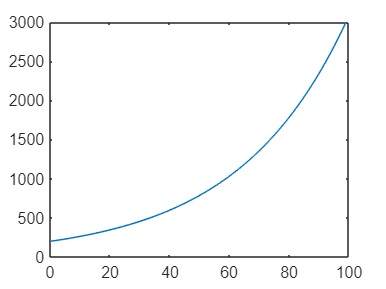

f_1 = 200;
f_2 = 3000;
count = 100;

t = 0:count-1;

f = @(c, n, f_1, f_2) f_1 .* (f_2/f_1) .^ (n / (c - 1));
fVals = f(count, t, f_1, f_2);

plot(t, fVals);

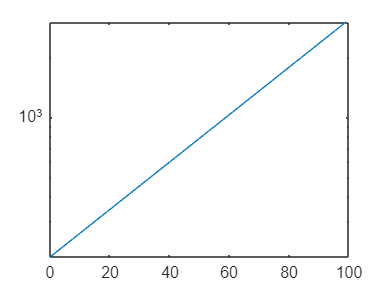

semilogy(t, fVals);

### Forrás

[világvége](https://github.com/compute-io/logspace/blob/master/lib/index.js)

## 2. feladat

f_p = 1;
f_1 = 0.1 * f_p;
f_2 = 10 * f_p;
count = 10;

t = f(count, 0:count-1, f_1, f_2)

t =     0.1000    0.1668    0.2783    0.4642    0.7743    1.2915    2.1544    3.5938    5.9948   10.0000
